Read netCDF files

1) Get the bathymetry and plot it

bathyfile='/ocean/sallen/allen/research/MEOPAR/NEMO-forcing/grid/bathy_downonegrid2.nc'

bathyfile = /ocean/sallen/allen/research/MEOPAR/NEMO-forcing/grid/bathy_downonegrid2.nc

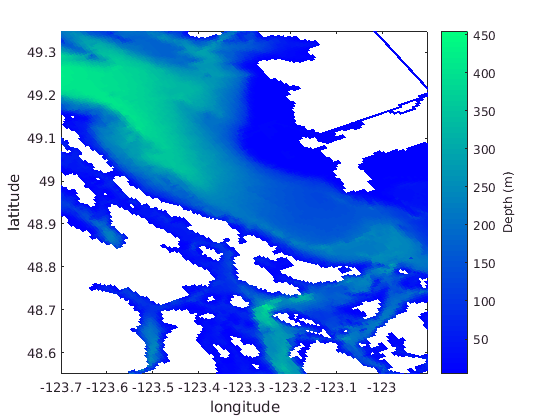

bathy = ncread(bathyfile, 'Bathymetry');
model_lats = ncread(bathyfile, 'nav_lat');
model_lons = ncread(bathyfile, 'nav_lon');
h = pcolor(model_lons, model_lats, bathy);
set(h, 'EdgeColor', 'none');
ax1=gca;
colormap(flipud('winter'));
cb = colorbar;
cb.Label.String = 'Depth (m)';
axis([-123.7 -122.9 48.55 49.35]);
xlabel('longitude');
ylabel('latitude');
hold on;

4) And now how to plot the velocity field.  We are on a staggered grid with the u-velocity 1/2 grid point in x and -1/2 grid point in y away from the v-velocity.  The files are huge, so we select what we want (choosing first hour and 27 grid point down) and then clear the big array

uvel_file = '/results/SalishSea/nowcast-blue/20feb17/SalishSea_1h_20170220_20170220_grid_U.nc'

uvel_file = /results/SalishSea/nowcast-blue/20feb17/SalishSea_1h_20170220_20170220_grid_U.nc

uvel_all = ncread(uvel_file, 'vozocrtx');
uvel = squeeze(uvel_all(:, :, 27, 1));
clear('uvel_all');
vvel_file = '/results/SalishSea/nowcast-blue/20feb17/SalishSea_1h_20170220_20170220_grid_V.nc'

vvel_file = /results/SalishSea/nowcast-blue/20feb17/SalishSea_1h_20170220_20170220_grid_V.nc

vvel_all = ncread(vvel_file, 'vomecrty');
vvel = squeeze(vvel_all(:, :, 27, 1));
clear('vvel_all');
depths = ncread(uvel_file, 'depthu');
depths(27)

ans = 98.0630

Unstagger

[u1, v1] = unstagger(uvel, vvel);

Rotate from grid coordindates to real north/east

[ueast, vnorth] = rotate_vel(u1, v1);

Plot

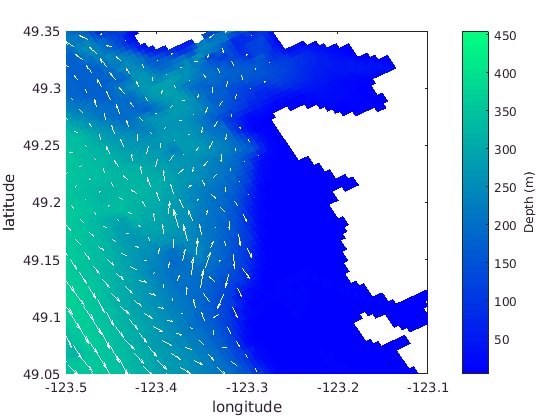

h = pcolor(model_lons, model_lats, bathy);
set(h, 'EdgeColor', 'none');
ax1=gca;
colormap(flipud('winter'));
cb = colorbar;
cb.Label.String = 'Depth (m)';
axis([-123.5 -123.1 49.05 49.35]);
xlabel('longitude');
ylabel('latitude');
hold on;
lowx = 250; higx=350; lowy=400; higy=500;
quiver(model_lons(lowx:3:higx, lowy:3:higy), model_lats(lowx:3:higx, lowy:3:higy),...
    ueast(lowx-1:3:higx-1, lowy-1:3:higy-1), vnorth(lowx-1:3:higx-1, lowy-1:3:higy-1), 'w')
    hold off;

Doug will pull the specific box for you and put all the times in one or two files. 

Salinity (reference salinity) and Temperature (conservative temperature) are in the grid T files and are called vosaline and votemper.